## Step 2 - カテゴリの空間配置

% clear; clc; close all;

### 1. Step 1の結果読み込み

try
    load('step1_results.mat', 'analysisData');
    fprintf('Step 1の結果を読み込みました\n');
catch
    error('step1_results.matが見つかりません。Step 1を先に実行してください。');
end

Step 1の結果を読み込みました



salesMatrix = analysisData.salesMatrix;
uniqueCategories = analysisData.uniqueCategories;
nCategories = length(uniqueCategories);

fprintf('カテゴリ数: %d\n', nCategories);

カテゴリ数: 34



% データ型を確認して適切なアクセス方法を決定
isCell = iscell(uniqueCategories);

### 2. データの前処理と正規化

normalizedMatrix = salesMatrix ./ max(salesMatrix, [], 2);
normalizedMatrix(isnan(normalizedMatrix)) = 0;

### 3. 主成分分析（PCA）による2次元配置

[coeff, score, latent, ~, explained] = pca(normalizedMatrix);
coords2D = score(:, 1:2);

fprintf('PCA完了\n');

PCA完了


fprintf('第1主成分の寄与率: %.1f%%\n', explained(1));

第1主成分の寄与率: 66.9%


fprintf('第2主成分の寄与率: %.1f%%\n', explained(2));

第2主成分の寄与率: 6.8%


fprintf('累積寄与率: %.1f%%\n', sum(explained(1:2)));

累積寄与率: 73.7%


### 4. 相関に基づく距離行列の作成

% カテゴリ間の相関行列を計算
corrMatrix = corrcoef(salesMatrix');
distanceMatrix = (1 - corrMatrix) / 2;
distanceMatrix(1:nCategories+1:end) = 0;

% 相関係数の高いペアを抽出（対角成分と下三角を除外）
upperTriangle = triu(corrMatrix, 1);  % 上三角行列（対角成分を除く）
[corrValues, sortIdx] = sort(upperTriangle(:), 'descend');

% 0でない相関値のみを対象とする
validIdx = corrValues ~= 0;
corrValues = corrValues(validIdx);
sortIdx = sortIdx(validIdx);

% 上位ペアの数を決定（レイアウト判断に十分な数を確保）
nTopPairs = min(20, length(corrValues));  % top20まで、または有効な相関数が20未満ならその数まで

% 行列インデックスから行・列番号を取得
[rowIdx, colIdx] = ind2sub(size(corrMatrix), sortIdx(1:nTopPairs));

% 高相関ペアの情報を保存（データ型に応じた処理）
topPairs = struct();
for i = 1:nTopPairs
    if isCell
        topPairs(i).category1 = uniqueCategories{rowIdx(i)};
        topPairs(i).category2 = uniqueCategories{colIdx(i)};
    else
        topPairs(i).category1 = char(uniqueCategories(rowIdx(i)));
        topPairs(i).category2 = char(uniqueCategories(colIdx(i)));
    end
    topPairs(i).correlation = corrValues(i);
    topPairs(i).idx1 = rowIdx(i);
    topPairs(i).idx2 = colIdx(i);
end

% 高相関ペアの表示
fprintf('\n■ カテゴリ間相関の上位%dペア:\n', nTopPairs);


■ カテゴリ間相関の上位20ペア:


fprintf('順位 | カテゴリ1              | カテゴリ2              | 相関係数\n');

順位 | カテゴリ1              | カテゴリ2              | 相関係数


fprintf('--------------------------------------------------------------------\n');

--------------------------------------------------------------------


for i = 1:min(10, nTopPairs)  % 最初の10ペアを表示
    fprintf('%2d位 | %-20s | %-20s | %6.3f\n', ...
        i, topPairs(i).category1, topPairs(i).category2, topPairs(i).correlation);
end

 1位 | 日記手帳                 | 趣味                   |  0.934
 2位 | 生活                   | 趣味                   |  0.853
 3位 | 日記手帳                 | 生活                   |  0.810
 4位 | コンピュータ               | 日記手帳                 |  0.783
 5位 | コンピュータ               | 趣味                   |  0.762
 6位 | 児童                   | 小学学参                 |  0.746
 7位 | ビジネス                 | 児童                   |  0.744
 8位 | 中学学参                 | 児童                   |  0.729
 9位 | 文庫                   | 文芸                   |  0.720
10位 | コンピュータ               | 生活                   |  0.707



% 日記手帳と趣味の相関を確認
if isCell
    nikki_idx = find(strcmp(uniqueCategories, '日記手帳'));
    shumi_idx = find(strcmp(uniqueCategories, '趣味'));
else
    nikki_idx = find(uniqueCategories == "日記手帳");
    shumi_idx = find(uniqueCategories == "趣味");
end

if ~isempty(nikki_idx) && ~isempty(shumi_idx)
    nikki_shumi_corr = corrMatrix(nikki_idx, shumi_idx);
    fprintf('\n※ 日記手帳と趣味の相関係数: %.3f\n', nikki_shumi_corr);
    
    % この相関が上位何位かを確認
    rank = find(corrValues >= nikki_shumi_corr, 1, 'last');
    if ~isempty(rank)
        fprintf('   → 全ペア中 第%d位\n', rank);
    end
end


※ 日記手帳と趣味の相関係数: 0.934


   → 全ペア中 第1位


### 5. 階層クラスタリングによるゾーン分け

distanceVector = squareform(distanceMatrix);
linkageMatrix = linkage(distanceVector, 'ward');


if nCategories < 10
    nClusters = 3;
elseif nCategories < 20
    nClusters = 4;
else
    nClusters = 5;
end

clusterIdx = cluster(linkageMatrix, 'MaxClust', nClusters);

for i = 1:nClusters
    fprintf('ゾーン%d: %d カテゴリ\n', i, sum(clusterIdx == i));
end

ゾーン1: 3 カテゴリ
ゾーン2: 6 カテゴリ
ゾーン3: 6 カテゴリ
ゾーン4: 15 カテゴリ
ゾーン5: 4 カテゴリ


### 6. レイアウトマップの可視化

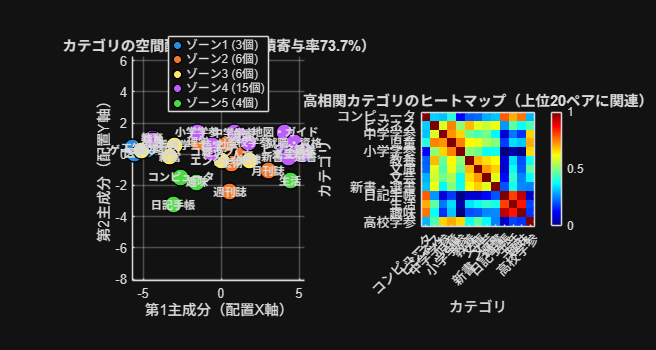

figure('Name', '書店カテゴリレイアウトマップ（修正版）', 'Position', [50 50 1500 800]);

% サブプロット1: PCAによる2次元配置
subplot(1, 2, 1);
hold on;

colors = lines(nClusters);
markerSize = 150;

for i = 1:nClusters
    idx = find(clusterIdx == i);
    if ~isempty(idx)
        scatter(coords2D(idx, 1), coords2D(idx, 2), ...
            markerSize, colors(i, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'LineWidth', 1);
    end
end

% カテゴリ名をラベル表示（データ型に応じた処理）
for i = 1:nCategories
    if isCell
        catName = uniqueCategories{i};
    else
        catName = char(uniqueCategories(i));
    end
    if length(catName) > 6
        catName = [catName(1:5) '..'];
    end
    text(coords2D(i, 1), coords2D(i, 2), catName, ...
        'HorizontalAlignment', 'center', 'FontSize', 8, 'FontWeight', 'bold');
end

xlabel('第1主成分（配置X軸）');
ylabel('第2主成分（配置Y軸）');
title(sprintf('カテゴリの空間配置（PCA: 累積寄与率%.1f%%）', sum(explained(1:2))));
grid on;
axis equal;

legendStr = arrayfun(@(i) sprintf('ゾーン%d (%d個)', i, sum(clusterIdx == i)), ...
    1:nClusters, 'UniformOutput', false);
legend(legendStr, 'Location', 'best');

% サブプロット2: 高相関カテゴリのヒートマップ
subplot(1, 2, 2);

% 高相関ペアに関連するカテゴリのインデックスを取得
relatedCatIdx = unique([rowIdx(1:nTopPairs); colIdx(1:nTopPairs)]);
nRelatedCats = length(relatedCatIdx);

% 関連カテゴリ間の相関行列を抽出
relatedCorrMatrix = corrMatrix(relatedCatIdx, relatedCatIdx);

% ヒートマップ表示
imagesc(relatedCorrMatrix);
colorbar;
colormap(jet);
caxis([0 1]);  % 正の相関のみ表示（0-1の範囲）

xlabel('カテゴリ');
ylabel('カテゴリ');
title(sprintf('高相関カテゴリのヒートマップ（上位%dペアに関連）', nTopPairs));

% カテゴリ名を軸ラベルに（データ型に応じた処理）
catLabels = cell(nRelatedCats, 1);
for i = 1:nRelatedCats
    if isCell
        catName = uniqueCategories{relatedCatIdx(i)};
    else
        catName = char(uniqueCategories(relatedCatIdx(i)));
    end
    if length(catName) > 8
        catLabels{i} = [catName(1:7) '..'];
    else
        catLabels{i} = catName;
    end
end

set(gca, 'XTick', 1:nRelatedCats, 'XTickLabel', catLabels, 'XTickLabelRotation', 45);
set(gca, 'YTick', 1:nRelatedCats, 'YTickLabel', catLabels);
axis square;

### 7. レイアウト提案の生成

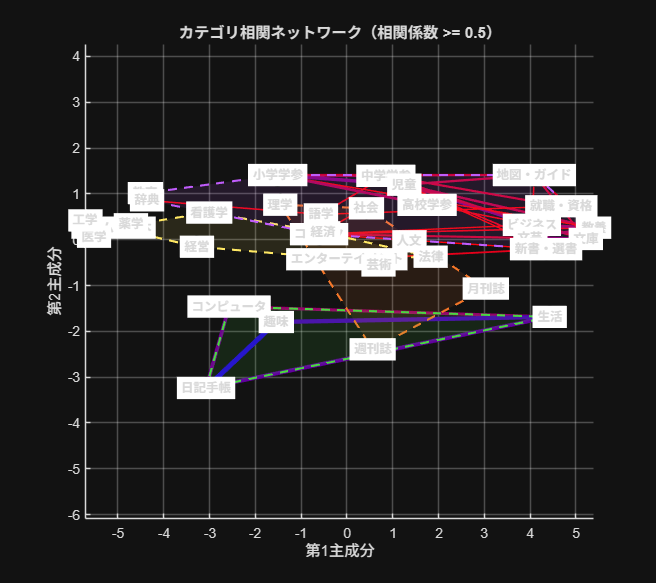

figure('Name', 'カテゴリ相関ネットワーク', 'Position', [100 100 900 800]);
hold on;

% 高相関のペアを線で結ぶ(閾値を設定)
corrThreshold = 0.5; % 相関係数0.5以上のみ表示

for i = 1:nCategories
    for j = i+1:nCategories
        if corrMatrix(i, j) >= corrThreshold
            % 線の太さを相関の強さに応じて調整
            lineWidth = 1 + 3 * (corrMatrix(i, j) - corrThreshold) / (1 - corrThreshold);
            
            % 線の色も相関の強さで変化(赤から青へ)
            colorIntensity = (corrMatrix(i, j) - corrThreshold) / (1 - corrThreshold);
            lineColor = [1-colorIntensity, 0, colorIntensity];
            
            % 線をプロット(ハンドルを取得)
            h = plot([coords2D(i, 1), coords2D(j, 1)], ...
                     [coords2D(i, 2), coords2D(j, 2)], ...
                     'LineWidth', lineWidth);
            
            % 透明度を設定(RGBに4番目の要素としてアルファ値を追加)
            h.Color = [lineColor, 0.5];
        end
    end
end

  for i = 1:nClusters
      idx = find(clusterIdx == i);
      if length(idx) >= 3
          k = convhull(coords2D(idx, 1), coords2D(idx, 2));
          patch(coords2D(idx(k), 1), coords2D(idx(k), 2), ...
                colors(i, :), 'FaceAlpha', 0.1, 'EdgeColor', colors(i, :), ...
                'LineWidth', 1.5, 'LineStyle', '--');
      end
  end

% カテゴリのプロット
for i = 1:nClusters
    idx = find(clusterIdx == i);
    if ~isempty(idx)
        scatter(coords2D(idx, 1), coords2D(idx, 2), ...
            200, colors(i, :), 'filled', ...
            'MarkerEdgeColor', 'k', 'LineWidth', 2);
    end
end


% カテゴリ名を表示（データ型に応じた処理）
for i = 1:nCategories
    if isCell
        catName = uniqueCategories{i};
    else
        catName = char(uniqueCategories(i));
    end
    text(coords2D(i, 1), coords2D(i, 2), catName, ...
        'HorizontalAlignment', 'center', 'FontSize', 9, ...
        'FontWeight', 'bold', 'BackgroundColor', 'white', ...
        'EdgeColor', 'none');
end

xlabel('第1主成分');
ylabel('第2主成分');
title(sprintf('カテゴリ相関ネットワーク（相関係数 >= %.1f）', corrThreshold));
grid on;
axis equal;

### 8. ゾーンごとの特徴分析

totalSales = sum(salesMatrix, 2);
centerDist = sqrt(coords2D(:,1).^2 + coords2D(:,2).^2);

% スコア計算（販売数と中心からの距離、相関の強さを考慮）
salesScore = totalSales / max(totalSales);
centerScore = 1 - (centerDist / max(centerDist));

% 各カテゴリの平均相関係数を計算（他カテゴリとの関連性の指標）
meanCorr = mean(abs(corrMatrix - eye(nCategories)), 2);
corrScore = meanCorr / max(meanCorr);

% 総合スコア（重み付け）
finalScore = 0.5 * salesScore + 0.2 * centerScore + 0.3 * corrScore;

[~, priorityOrder] = sort(finalScore, 'descend');

fprintf('\n■ 推奨配置（総合スコア順）:\n');


■ 推奨配置（総合スコア順）:


fprintf('順位 | カテゴリ名               | ゾーン | 販売数   | 平均相関 | スコア\n');

順位 | カテゴリ名               | ゾーン | 販売数   | 平均相関 | スコア


fprintf('------------------------------------------------------------------------\n');

------------------------------------------------------------------------



for i = 1:min(15, length(priorityOrder))
    catIdx = priorityOrder(i);
    if isCell
        catName = uniqueCategories{catIdx};
    else
        catName = char(uniqueCategories(catIdx));
    end
    fprintf('%2d位 | %-20s | Zone%d | %8d | %.3f    | %.3f\n', ...
        i, catName, clusterIdx(catIdx), ...
        round(totalSales(catIdx)), meanCorr(catIdx), finalScore(catIdx));
end

 1位 | コミック                 | Zone4 |  1383186 | 0.271    | 0.905
 2位 | 児童                   | Zone4 |   325607 | 0.349    | 0.549
 3位 | 文庫                   | Zone4 |   630459 | 0.332    | 0.523
 4位 | 月刊誌                  | Zone2 |   856595 | 0.139    | 0.514
 5位 | 中学学参                 | Zone4 |    37536 | 0.309    | 0.415
 6位 | 語学                   | Zone4 |    49238 | 0.263    | 0.410
 7位 | 小学学参                 | Zone4 |    89262 | 0.284    | 0.398
 8位 | エンターテイメント            | Zone3 |    51383 | 0.231    | 0.397
 9位 | ビジネス                 | Zone4 |    99534 | 0.359    | 0.394
10位 | 文芸                   | Zone4 |   111247 | 0.330    | 0.376
11位 | 趣味                   | Zone5 |   180914 | 0.218    | 0.365
12位 | 高校学参                 | Zone4 |    40620 | 0.247    | 0.355
13位 | 週刊誌                  | Zone2 |   199600 | 0.197    | 0.351
14位 | 地図・ガイド               | Zone4 |   104020 | 0.300    | 0.337
15位 | 新書・選書                | Zone4 |    87047 | 0.308    | 0.337


### 9. 動線シミュレーション図の作成

fprintf('\n■ ゾーン別特徴分析:\n');


■ ゾーン別特徴分析:


zoneCharacteristics = struct();

for z = 1:nClusters
    zoneCategories = find(clusterIdx == z);
    if isempty(zoneCategories)
        continue;
    end
    
    zoneSales = salesMatrix(zoneCategories, :);
    totalZoneSales = sum(zoneSales(:));
    avgZoneSales = mean(zoneSales(:));
    
    % ゾーン内の相関の強さ
    zoneCorr = corrMatrix(zoneCategories, zoneCategories);
    avgZoneCorr = mean(zoneCorr(zoneCorr ~= 1));  % 対角成分を除く
    
    centerX = mean(coords2D(zoneCategories, 1));
    centerY = mean(coords2D(zoneCategories, 2));
    
    fprintf('\n【ゾーン %d】\n', z);
    fprintf('  構成: %d カテゴリ\n', length(zoneCategories));
    fprintf('  総販売: %d 冊\n', round(totalZoneSales));
    fprintf('  平均販売: %.1f 冊/日\n', avgZoneSales);
    fprintf('  ゾーン内平均相関: %.3f\n', avgZoneCorr);
    fprintf('  配置重心: (%.2f, %.2f)\n', centerX, centerY);
    
    zoneTotalSales = sum(zoneSales, 2);
    [maxSales, maxIdx] = max(zoneTotalSales);
    if isCell
        repCatName = uniqueCategories{zoneCategories(maxIdx)};
    else
        repCatName = char(uniqueCategories(zoneCategories(maxIdx)));
    end
    fprintf('  代表カテゴリ: %s (販売数:%d)\n', repCatName, round(maxSales));
    
    % ゾーン内のカテゴリ一覧
    fprintf('  カテゴリ一覧: ');
    for k = 1:length(zoneCategories)
        if isCell
            catName = uniqueCategories{zoneCategories(k)};
        else
            catName = char(uniqueCategories(zoneCategories(k)));
        end
        fprintf('%s', catName);
        if k < length(zoneCategories)
            fprintf(', ');
        end
    end
    fprintf('\n');
    
    zoneCharacteristics(z).categories = zoneCategories;
    zoneCharacteristics(z).totalSales = totalZoneSales;
    zoneCharacteristics(z).avgCorrelation = avgZoneCorr;
    zoneCharacteristics(z).center = [centerX, centerY];
end


【ゾーン 1】


  構成: 3 カテゴリ


  総販売: 6931 冊


  平均販売: 6.3 冊/日


  ゾーン内平均相関: 0.175


  配置重心: (-5.32, 0.27)


  代表カテゴリ: 工学 (販売数:5619)


  カテゴリ一覧: 

医学

, 

工学

, 

薬学


【ゾーン 2】


  構成: 6 カテゴリ


  総販売: 1107886 冊


  平均販売: 504.5 冊/日


  ゾーン内平均相関: 0.112


  配置重心: (0.77, -0.43)


  代表カテゴリ: 月刊誌 (販売数:856595)


  カテゴリ一覧: 

人文

, 

月刊誌

, 

理学

, 

社会

, 

芸術

, 

週刊誌


【ゾーン 3】


  構成: 6 カテゴリ


  総販売: 85083 冊


  平均販売: 38.7 冊/日


  ゾーン内平均相関: 0.157


  配置重心: (-1.68, 0.01)


  代表カテゴリ: エンターテイメント (販売数:51383)


  カテゴリ一覧: 

エンターテイメント

, 

ゲーム攻略本

, 

法律

, 

看護学

, 

経営

, 

経済


【ゾーン 4】


  構成: 15 カテゴリ


  総販売: 3063763 冊


  平均販売: 558.1 冊/日


  ゾーン内平均相関: 0.461


  配置重心: (1.61, 0.66)


  代表カテゴリ: コミック (販売数:1383186)


  カテゴリ一覧: 

コミック

, 

ビジネス

, 

中学学参

, 

児童

, 

地図・ガイド

, 

小学学参

, 

就職・資格

, 

教育

, 

教養

, 

文庫

, 

文芸

, 

新書・選書

, 

語学

, 

辞典

, 

高校学参


【ゾーン 5】


  構成: 4 カテゴリ


  総販売: 431909 冊


  平均販売: 295.0 冊/日


  ゾーン内平均相関: 0.808


  配置重心: (-0.69, -2.04)


  代表カテゴリ: 趣味 (販売数:180914)


  カテゴリ一覧: 

コンピュータ

, 

日記手帳

, 

生活

, 

趣味

### 10. 結果の保存

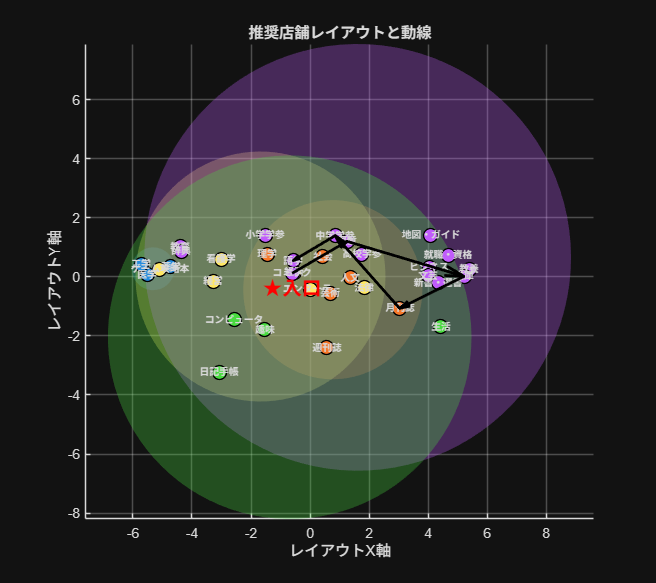

figure('Name', '推奨動線レイアウト', 'Position', [100 100 900 800]);
hold on;

% ゾーン領域を描画
theta = linspace(0, 2*pi, 100);
for z = 1:nClusters
    zoneCategories = find(clusterIdx == z);
    if isempty(zoneCategories)
        continue;
    end
    
    centerX = mean(coords2D(zoneCategories, 1));
    centerY = mean(coords2D(zoneCategories, 2));
    
    if length(zoneCategories) > 1
        radius = max(sqrt((coords2D(zoneCategories, 1) - centerX).^2 + ...
                         (coords2D(zoneCategories, 2) - centerY).^2)) * 1.2;
    else
        radius = 0.5;
    end
    
    fill(centerX + radius*cos(theta), centerY + radius*sin(theta), ...
         colors(z, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
end

% カテゴリをプロット
for i = 1:nClusters
    idx = find(clusterIdx == i);
    if ~isempty(idx)
        scatter(coords2D(idx, 1), coords2D(idx, 2), ...
            100, colors(i, :), 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 1);
    end
end

% カテゴリ名を表示（データ型に応じた処理）
for i = 1:nCategories
    if isCell
        catName = uniqueCategories{i};
    else
        catName = char(uniqueCategories(i));
    end
    if length(catName) > 6
        catName = [catName(1:5) '..'];
    end
    text(coords2D(i, 1), coords2D(i, 2), catName, ...
        'HorizontalAlignment', 'center', 'FontSize', 7, 'FontWeight', 'bold');
end

% 推奨動線を矢印で描画（上位カテゴリ間）
for i = 1:min(5, length(priorityOrder)-1)
    fromIdx = priorityOrder(i);
    toIdx = priorityOrder(i+1);
    
    quiver(coords2D(fromIdx, 1), coords2D(fromIdx, 2), ...
           coords2D(toIdx, 1) - coords2D(fromIdx, 1), ...
           coords2D(toIdx, 2) - coords2D(fromIdx, 2), ...
           0, 'k', 'LineWidth', 2, 'MaxHeadSize', 0.5);
end

% 入口マーク
text(coords2D(priorityOrder(1), 1), coords2D(priorityOrder(1), 2) - 0.5, ...
     '★入口', 'FontSize', 14, 'FontWeight', 'bold', ...
     'HorizontalAlignment', 'center', 'Color', 'r');

xlabel('レイアウトX軸');
ylabel('レイアウトY軸');
title('推奨店舗レイアウトと動線');
grid on;
axis equal;

### 11. 結果の保存

step2Results.coords2D = coords2D;
step2Results.clusterIdx = clusterIdx;
step2Results.distanceMatrix = distanceMatrix;
step2Results.corrMatrix = corrMatrix;
step2Results.topPairs = topPairs;
step2Results.finalScore = finalScore;
step2Results.priorityOrder = priorityOrder;
step2Results.explained = explained;
step2Results.zoneCharacteristics = zoneCharacteristics;

save('step2_results.mat', 'step2Results', 'analysisData');
fprintf('\n結果を step2_results.mat に保存しました\n');


結果を step2_results.mat に保存しました
